# Load parameter calculation

## Bus data analysis

### Import NPCC 140-bus matpower base case

% Load original matpower case
load("D:\EERL\NY-Simple-Net\NY-Simple-Net-main\Data\NPCC140\Case\npcc.mat", "-mat", "mpc")
% Define matpower matrices index constants
define_constants;
% Convert MPC matrices to table
originalMpcBaseMVA = mpc.baseMVA;
originalMpcGen = array2table(mpc.gen,"VariableNames", ...
    ["GEN_BUS","PG","QG","QMAX","QMIN","VG","MBASE","GEN_STATUS","PMAX","PMIN","PC1","PC2",...
    "QC1MIN","QC1MAX","QC2MIN","QC2MAX","RAMP_AGC","RAMP_10","RAMP_30","RAMP_Q","APF"]);
originalMpcBus = array2table(mpc.bus, "VariableNames", ...
    ["BUS_I","BUS_TYPE","PD","QD","GS","BS","BUS_AREA","VM","VA","BASE_KV","ZONE","VMAX","VMIN"]);
originalMpcBranch = array2table(mpc.branch, "VariableNames", ...
    ["F_BUS","T_BUS","BR_R","BR_X","BR_B","RATE_A","RATE_B","RATE_C","TAP","SHIFT","BR_STATUS","ANGMIN","ANGMAX"]);

### Load bus type and zone table in NYS

NYSBus = readtable("D:\EERL\NY-Simple-Net\NY-Simple-Net-main\Data\NPCC140\bus_ny_type_zone.csv");
NYSBus.zoneID = categorical(NYSBus.zoneID);
% Subset bus with bus type
NYSBusPQ = NYSBus(NYSBus.busType == 1, :);
NYSBusPV = NYSBus(NYSBus.busType == 2, :);
NYSBusSlack = NYSBus(NYSBus.busType == 3, :);
NYSBusGen = [NYSBusPV; NYSBusSlack];
% Subset bus with load connected, could be all types of bus
NYSBusWLoad = NYSBus(NYSBus.numLoad > 0, :)

NYSBusWLoad = 22×21 table
    busIdx    busType    u         name          Vn     vmax    vmin      v0          a0        xcoord     ycoord    area    zone    owner    numGen    sumGenP0    sumGenQ0    numLoad    sumLoadP0    sumLoadQ0    zoneID
    ______    _______    _    _______________    ___    ____    ____    _______    _________    _______    ______    ____    ____    _____    ______

### Bus with load summary tables

46 buses in NYS, 22 of them have load: 8 PQ, 13 PV, 1 slack

- No bus with load in zone B, G, I, J.

- No bus in zone I.

- We have to manually add load in zone B, G, I, J.

- Zone B only has one bus, so the load has to be put on that bus.

- Zone I has no bus, so we allocate the load to zone H. (Or we could add a load bus in zone I)

- Zone J and G have no bus with load so we distrubute the load evenly among the bus.

- Other zones: allocate load to the buses with load

groupsummary(NYSBusWLoad, "busType")

ans = 3×2 table
    busType    GroupCount
    _______    __________

       1            8    
       2           13    
       3            1    


groupsummary(NYSBusWLoad, "zoneID", "sum", ["sumLoadP0","sumLoadQ0"])

ans = 7×4 table
    zoneID    GroupCount    sum_sumLoadP0    sum_sumLoadQ0
    ______    __________    _____________    _____________

      A           8              33.2             6.64    
      C           4             11.76             1.41    
      D           1              2.08             0.17    
      E           4             11.78            1.275    
      F           2              8.77             1.42    
      H           1              1.02                0    
      K           2                27             6.25    


groupsummary(NYSBus, ["zoneID","busType"], "sum", ["sumGenP0","sumGenQ0","sumLoadP0","sumLoadQ0"])

ans = 16×7 table
    zoneID    busType    GroupCount    sum_sumGenP0    sum_sumGenQ0    sum_sumLoadP0    sum_sumLoadQ0
    ______    _______    __________    ____________    ____________    _____________    _____________

      A          1           3                 0               0            7.89             2.36    
      A          2           7             43.55          4.8008           25.31             4.28    
      B          1           1                 0               0               0                0    
      C          1           5                 0               0            1.43             0.25    
      C          2           5             10.48          4.9277           10.33             1.16    
      D          1           1

### Load bus and ratio calculation

zoneIDs = {'A','B','C','D','E','F','G','H','I','J','K'};
loadBusZone = cell(11, 1);
loadRatioZone = cell(11, 1);
numLoadBusZone = zeros(11, 1);
for i=1:11
    % With load bus
    loadBusTable = NYSBusWLoad(NYSBusWLoad.zoneID == zoneIDs(i), :);
    loadBusZone{i} = loadBusTable.busIdx;
    loadRatioZone{i} = loadBusTable.sumLoadP0/sum(loadBusTable.sumLoadP0);
    % If there are no bus with load, evenly distribute the load among buses
    if isempty(loadBusZone{i})
        loadBusZone{i} = NYSBus.busIdx(NYSBus.zoneID == zoneIDs(i));
        loadRatioZone{i} = 1/length(loadBusZone{i});
    end
    numLoadBusZone(i) = length(loadBusZone{i});
end
% Allocate load in zone I to the bus in zone H
loadBusZone{9} = loadBusZone{8};
loadRatioZone{9} = 1;
numLoadBusZone(9) = 1;
numLoadBusTot = sum(numLoadBusZone)

numLoadBusTot =     32


## Load data analysis

### Import 2019 NYISO zonal load data

% 2019 whole year DAM load forecast data
% loadForecast = importLoadForecast("D:\EERL\NY-Simple-Net\NY-Simple-Net-main\Data\NYISO_DAM_Load_2019.csv");
% 2019 RTM hourly actual load data
loadFileDir = "D:\EERL\2019_NYISO\2019_RTM_Integrated_Actual_Load\";
loadFileName = "2019*";
loadDataStore = fileDatastore(loadFileDir + loadFileName, "ReadFcn", @importActIntegLoad, "UniformRead", true);
loadAll = readall(loadDataStore);
clear loadDataStore;

### Load data cleaning

- 03/10/2019 02:00 data is missing: linear interpolation.

- 11/03/2019 01:00 has duplicates: remove the duplicate record.

% Clean missing data
loadAllMissing = loadAll(loadAll.TimeStamp >= '03/10/2019 01:00:00' & loadAll.TimeStamp < '03/10/2019 03:00:01' | ismissing(loadAll.TimeStamp),:);
loadAllAddMissing = groupsummary(loadAllMissing, ["ZoneName","PTID"],"mean","HourlyLoad");
TimeStamp = datetime(repelem("03/10/2019 02:00:00", 11)',"Format","MM/dd/uuuu HH:mm:ss");
loadAllAddMissing = addvars(loadAllAddMissing, TimeStamp, 'Before', 'ZoneName');
loadAllAddMissing = removevars(loadAllAddMissing, "GroupCount");
loadAllAddMissing.Properties.VariableNames(end) = "HourlyLoad";

% Clean duplicated data
loadAllNoDup = loadAll(loadAll.TimeStamp ~= '11/03/2019 01:00:00', :);
loadAllDup = loadAll(loadAll.TimeStamp == '11/03/2019 01:00:00', :);
loadAllRemoveDup = groupsummary(loadAllDup, ["ZoneName","PTID"],"mean","HourlyLoad");
TimeStamp = datetime(repelem("11/03/2019 01:00:00", 11)',"Format","MM/dd/uuuu HH:mm:ss");
loadAllRemoveDup = addvars(loadAllRemoveDup, TimeStamp, 'Before', 'ZoneName');
loadAllRemoveDup = removevars(loadAllRemoveDup, "GroupCount");
loadAllRemoveDup.Properties.VariableNames(end) = "HourlyLoad";
loadAllCleaned = [loadAllNoDup; loadAllAddMissing; loadAllRemoveDup];
loadAllCleaned = sortrows(loadAllCleaned, "TimeStamp");

#### Add zone ID info

loadAllCleaned.ZoneID(loadAllCleaned.ZoneName == "WEST") = "A";
loadAllCleaned.ZoneID(loadAllCleaned.ZoneName == "GENESE") = "B";
loadAllCleaned.ZoneID(loadAllCleaned.ZoneName == "CENTRL") = "C";
loadAllCleaned.ZoneID(loadAllCleaned.ZoneName == "NORTH") = "D";
loadAllCleaned.ZoneID(loadAllCleaned.ZoneName == "MHK VL") = "E";
loadAllCleaned.ZoneID(loadAllCleaned.ZoneName == "CAPITL") = "F";
loadAllCleaned.ZoneID(loadAllCleaned.ZoneName == "HUD VL") = "G";
loadAllCleaned.ZoneID(loadAllCleaned.ZoneName == "MILLWD") = "H";
loadAllCleaned.ZoneID(loadAllCleaned.ZoneName == "DUNWOD") = "I";
loadAllCleaned.ZoneID(loadAllCleaned.ZoneName == "N.Y.C.") = "J";
loadAllCleaned.ZoneID(loadAllCleaned.ZoneName == "LONGIL") = "K";
loadAllCleaned.ZoneID = categorical(loadAllCleaned.ZoneID);

### NYISO total hourly load

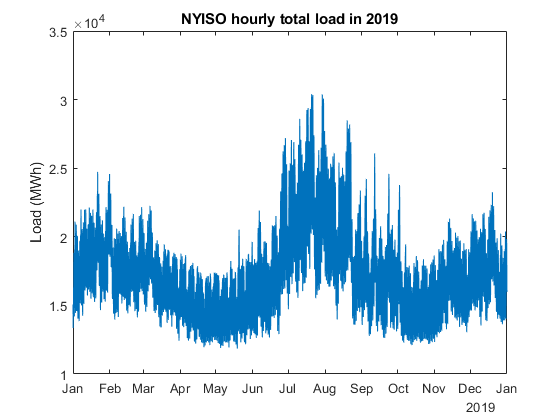

loadAllTot = groupsummary(loadAllCleaned, "TimeStamp", "sum", "HourlyLoad");
plot(loadAllTot.TimeStamp, loadAllTot.sum_HourlyLoad)
ylabel("Load (MWh)");
title("NYISO hourly total load in 2019");

### Sample hours (median, min, max)

medianLoad = median(loadAllTot.sum_HourlyLoad);
[~, medianIdx] = min(abs(loadAllTot.sum_HourlyLoad - medianLoad));
medianTimeStamp = loadAllTot.TimeStamp(medianIdx);
[minLoad, minIdx] = min(loadAllTot.sum_HourlyLoad);
minTimeStamp = loadAllTot.TimeStamp(minIdx);
[maxLoad, maxIdx] = max(loadAllTot.sum_HourlyLoad);
maxTimeStamp = loadAllTot.TimeStamp(maxIdx);
sampledHoursTable = cell2table({medianTimeStamp, medianLoad; minTimeStamp, minLoad; maxTimeStamp, maxLoad}, ...
    "RowNames",["median","min","max"],"VariableName",["TimeStamp","HourlyLoad"])

sampledHoursTable = 3×2 table
                   TimeStamp         HourlyLoad
              ___________________    __________

    median    01/13/2019 23:00:00      17425   
    min       05/19/2019 04:00:00      11854   
    max       07/20/2019 16:00:00      30397   


medianLoadZonal = loadAllCleaned(loadAllCleaned.TimeStamp == medianTimeStamp, :)

medianLoadZonal = 11×5 table
         TimeStamp         ZoneName    PTID     HourlyLoad    ZoneID
    ___________________    ________    _____    __________    ______

    01/13/2019 23:00:00     CAPITL     61757      1412.2        F   
    01/13/2019 23:00:00     CENTRL     61754        1983        C   
    01/13/2019 23:00:00     DUNWOD     61760       632.5        I   
    01/13/2019 23:00:00     GENESE     61753      1063.3        B   
    01/13/2019 23:00:00     HUD VL     61758      1093.6        G   
    01/13/2019 23:00:00     LONGIL     61762      2162.7        K   
    01/13/2019 23:00:00     MHK VL     61756      1031.1        E   
    01/13/2019 23:00:00     MILLWD     61759       320.9        H   
    01/13/2019 23:00:00     N.Y.C.     61761      5431.2        J   
    01/13/2019 23:00:00     NORTH      61

minLoadZonal = loadAllCleaned(loadAllCleaned.TimeStamp == minTimeStamp, :)

minLoadZonal = 11×5 table
         TimeStamp         ZoneName    PTID     HourlyLoad    ZoneID
    ___________________    ________    _____    __________    ______

    05/19/2019 04:00:00     CAPITL     61757       882.3        F   
    05/19/2019 04:00:00     CENTRL     61754      1254.6        C   
    05/19/2019 04:00:00     DUNWOD     61760       453.5        I   
    05/19/2019 04:00:00     GENESE     61753       737.3        B   
    05/19/2019 04:00:00     HUD VL     61758       716.9        G   
    05/19/2019 04:00:00     LONGIL     61762      1496.3        K   
    05/19/2019 04:00:00     MHK VL     61756       561.7        E   
    05/19/2019 04:00:00     MILLWD     61759       172.8        H   
    05/19/2019 04:00:00     N.Y.C.     61761      3945.5        J   
    05/19/2019 04:00:00     NORTH      61755

maxLoadZonal = loadAllCleaned(loadAllCleaned.TimeStamp == maxTimeStamp, :)

maxLoadZonal = 11×5 table
         TimeStamp         ZoneName    PTID     HourlyLoad    ZoneID
    ___________________    ________    _____    __________    ______

    07/20/2019 16:00:00     CAPITL     61757      2224.3        F   
    07/20/2019 16:00:00     CENTRL     61754      2591.6        C   
    07/20/2019 16:00:00     DUNWOD     61760      1312.7        I   
    07/20/2019 16:00:00     GENESE     61753      1841.1        B   
    07/20/2019 16:00:00     HUD VL     61758      2180.2        G   
    07/20/2019 16:00:00     LONGIL     61762      5305.1        K   
    07/20/2019 16:00:00     MHK VL     61756      1304.9        E   
    07/20/2019 16:00:00     MILLWD     61759       652.3        H   
    07/20/2019 16:00:00     N.Y.C.     61761       10015        J   
    07/20/2019 16:00:00     NORTH      61755

## Allocate load to bus

### Method 1: Evenly distribute the load

NYSBusMedianLoadEvenly = addLoadEvenly(medianLoadZonal,NYSBus,zoneIDs)

NYSBusMedianLoadEvenly = 46×7 table
    busIdx    busType         name          area    zoneID      PD        QD  
    ______    _______    _______________    ____    ______    ______    ______

      37         1       {'NEW SEATHED'}     2        G       182.27    37.011
      38         1       {'GILBOA'     }     2        E       114.57    23.264
      39         1       {'LEEDS'      }     2        G       182.27    37.011
      40         1       {'NEW SEATHED'}     2        F       470.73    95.586
      41         1       {'ROTTERDAM'  }     2        F       470.73    95.586
      42         2       {'ALBANY'     }     2        F       470.73    95.586
      43         1       {'EDIC'       }     2        E       114.57    23.264
      44      

NYSBusMinLoadEvenly = addLoadEvenly(minLoadZonal,NYSBus,zoneIDs)

NYSBusMinLoadEvenly = 46×7 table
    busIdx    busType         name          area    zoneID      PD        QD  
    ______    _______    _______________    ____    ______    ______    ______

      37         1       {'NEW SEATHED'}     2        G       119.48    24.262
      38         1       {'GILBOA'     }     2        E       62.411    12.673
      39         1       {'LEEDS'      }     2        G       119.48    24.262
      40         1       {'NEW SEATHED'}     2        F        294.1     59.72
      41         1       {'ROTTERDAM'  }     2        F        294.1     59.72
      42         2       {'ALBANY'     }     2        F        294.1     59.72
      43         1       {'EDIC'       }     2        E       62.411    12.673
      44         

NYSBusMaxLoadEvenly = addLoadEvenly(maxLoadZonal,NYSBus,zoneIDs)

NYSBusMaxLoadEvenly = 46×7 table
    busIdx    busType         name          area    zoneID      PD        QD  
    ______    _______    _______________    ____    ______    ______    ______

      37         1       {'NEW SEATHED'}     2        G       363.37    73.785
      38         1       {'GILBOA'     }     2        E       144.99    29.441
      39         1       {'LEEDS'      }     2        G       363.37    73.785
      40         1       {'NEW SEATHED'}     2        F       741.43    150.55
      41         1       {'ROTTERDAM'  }     2        F       741.43    150.55
      42         2       {'ALBANY'     }     2        F       741.43    150.55
      43         1       {'EDIC'       }     2        E       144.99    29.441
      44         

### Method 2: Distribute load according to the original MPC load level

NYSBusMedianLoadWeighted = addLoadWeighted(medianLoadZonal,loadRatioZone,loadBusZone,numLoadBusTot,NYSBus,zoneIDs,numLoadBusZone)

NYSBusMedianLoadWeighted = 46×7 table
    busIdx    busType         name          area    zoneID      PD        QD  
    ______    _______    _______________    ____    ______    ______    ______

      37         1       {'NEW SEATHED'}     2        G       182.27    37.011
      38         1       {'GILBOA'     }     2        E            0         0
      39         1       {'LEEDS'      }     2        G       182.27    37.011
      40         1       {'NEW SEATHED'}     2        F            0         0
      41         1       {'ROTTERDAM'  }     2        F       1127.2    228.88
      42         2       {'ALBANY'     }     2        F       285.02    57.875
      43         1       {'EDIC'       }     2        E            0         0
      44    

NYSBusMinLoadWeighted = addLoadWeighted(minLoadZonal,loadRatioZone,loadBusZone,numLoadBusTot,NYSBus,zoneIDs,numLoadBusZone)

NYSBusMinLoadWeighted = 46×7 table
    busIdx    busType         name          area    zoneID      PD        QD  
    ______    _______    _______________    ____    ______    ______    ______

      37         1       {'NEW SEATHED'}     2        G       119.48    24.262
      38         1       {'GILBOA'     }     2        E            0         0
      39         1       {'LEEDS'      }     2        G       119.48    24.262
      40         1       {'NEW SEATHED'}     2        F            0         0
      41         1       {'ROTTERDAM'  }     2        F       704.23       143
      42         2       {'ALBANY'     }     2        F       178.07    36.159
      43         1       {'EDIC'       }     2        E            0         0
      44       

NYSBusMaxLoadWeighted = addLoadWeighted(maxLoadZonal,loadRatioZone,loadBusZone,numLoadBusTot,NYSBus,zoneIDs,numLoadBusZone)

NYSBusMaxLoadWeighted = 46×7 table
    busIdx    busType         name          area    zoneID      PD        QD  
    ______    _______    _______________    ____    ______    ______    ______

      37         1       {'NEW SEATHED'}     2        G       363.37    73.785
      38         1       {'GILBOA'     }     2        E            0         0
      39         1       {'LEEDS'      }     2        G       363.37    73.785
      40         1       {'NEW SEATHED'}     2        F            0         0
      41         1       {'ROTTERDAM'  }     2        F       1775.4    360.51
      42         2       {'ALBANY'     }     2        F       448.92    91.157
      43         1       {'EDIC'       }     2        E            0         0
      44       

### Write the results

dataDir = "D:\EERL\NY-Simple-Net\NY-Simple-Net-main\Data\";
save(dataDir+"NYSHourlyLoadSamplesEvenly.mat","NYSBusMaxLoadEvenly","NYSBusMinLoadEvenly","NYSBusMedianLoadEvenly","-mat");
save(dataDir+"NYSHourlyLoadSamplesWeighted.mat","NYSBusMaxLoadWeighted","NYSBusMinLoadWeighted","NYSBusMedianLoadWeighted","-mat");

## Function to allocate load

### Method 1

function NYSBusLoadEven = addLoadEvenly(hourlyLoadZonal,NYSBus,zoneIDs)
    NYSBusLoadEven = [];
    for i=1:11
        NYSBusZone = NYSBus(NYSBus.zoneID == zoneIDs(i), :);
        zoneLoadTot = hourlyLoadZonal.HourlyLoad(hourlyLoadZonal.ZoneID == categorical(zoneIDs(i)));
        NYSBusZone.PD = zoneLoadTot/height(NYSBusZone)*ones(height(NYSBusZone), 1);
        NYSBusLoadEven = [NYSBusLoadEven; NYSBusZone];
        if i == 9
            % Manually add load in zone I to the bus in zone H
            NYSBusLoadEven.PD(NYSBusLoadEven.busIdx == 74) = NYSBusLoadEven.PD(NYSBusLoadEven.busIdx == 74) + zoneLoadTot;
        end
    end
    
    powerFactor = 0.98;
    NYSBusLoadEven.QD = NYSBusLoadEven.PD * tan(acos(powerFactor));
    NYSBusLoadEven = NYSBusLoadEven(:, ["busIdx","busType","name","area","zoneID","PD","QD"]);
    NYSBusLoadEven = sortrows(NYSBusLoadEven, "busIdx");
end


### Method 2

function NYSBusNew = addLoadWeighted(hourlyLoadZonal,loadRatioZone,loadBusZone,numLoadBusTot,NYSBusOld,zoneIDs,numLoadBusZone)
    zoneLoadBus = cell(11, 1);
    loadBusIdx = zeros(numLoadBusTot, 1);
    loadBusLoad = zeros(numLoadBusTot, 1);
    n = 1;
    for i=1:11
        zoneLoadTot = hourlyLoadZonal.HourlyLoad(hourlyLoadZonal.ZoneID == categorical(zoneIDs(i)));
        zoneLoadBus{i} = loadRatioZone{i}*zoneLoadTot;
        loadBusIdx(n:n+numLoadBusZone(i)-1) = loadBusZone{i};
        loadBusLoad(n:n+numLoadBusZone(i)-1) = zoneLoadBus{i};
        n = n+numLoadBusZone(i);
    end
    busWLoad = array2table([loadBusIdx, loadBusLoad], "VariableNames", ["busIdx", "PD"]);
    busWLoadCleaned = groupsummary(busWLoad, "busIdx", "sum", "PD");
    busWLoadCleaned.Properties.VariableNames(3) = "PD";
    
    % Join table
    NYSBusNew = outerjoin(NYSBusOld,busWLoadCleaned,"Type","left","Keys","busIdx","MergeKeys",true, ...
        "LeftVariables",["busIdx","busType","name","area","zoneID"],"RightVariables","PD");
    NYSBusNew.PD = fillmissing(NYSBusNew.PD, "constant", 0);
    powerFactor = 0.98;
    NYSBusNew.QD = NYSBusNew.PD * tan(acos(powerFactor));
end